clear;
clc;
close all;

% Script written by Jo Wayne Tan, jwt617, to produce plots for the second
% CFD coursework. 26/01/2021.

## Read data from txt files

rho = dlmread('rho.txt');
p = dlmread('p.txt');
u = dlmread('u.txt');
Mach = dlmread('Mach.txt');
ent = dlmread('entropy.txt');

% Read data from shock_analytic.dat
data_shock = dlmread('shock_analytic.dat', '', 1, 0);
n = length(data_shock);
x_shock = data_shock([1:n], 1);
rho_shock = data_shock([1:n], 2);
p_shock = data_shock([1:n], 3);
v_shock = data_shock([1:n], 4);
m_shock = data_shock([1:n], 5);
e_shock = data_shock([1:n], 6);

## Define Meshes

x_100 = linspace(-2,2,100);
x_200 = linspace(-2,2,200);
x_300 = linspace(-2,2,300);

## Density

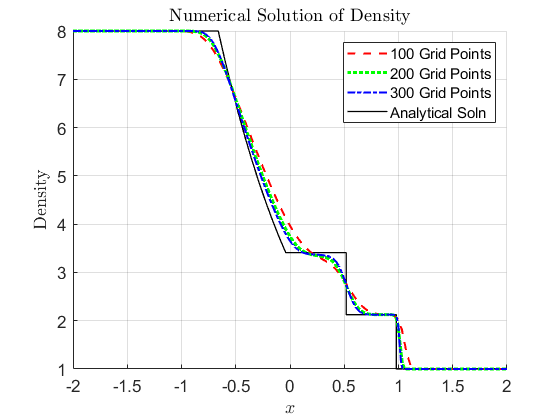

figure (1)
hold on
den_anal = plot(x_shock, rho_shock, 'k', 'LineWidth', 1);
den_100 = plot(x_100, rho(1,1:100), '--', 'MarkerSize', 4, 'color', 'r', 'LineWidth', 1.5); % o
den_200 = plot(x_200, rho(2,1:200), ':', 'MarkerSize', 4, 'color', 'g', 'LineWidth', 2.25); % x
den_300 = plot(x_300, rho(3,1:300), '-.', 'MarkerSize', 4, 'color', 'b', 'LineWidth', 1.5); % ^
title('Numerical Solution of Density', 'interpreter', 'latex', 'FontSize', 10);
ylabel('Density', 'interpreter', 'latex', 'FontSize', 10), xlabel('$x$', 'interpreter', 'latex', 'FontSize', 10);
set(gca, 'FontSize', 12.5);
L = legend([den_100 den_200 den_300 den_anal], '100 Grid Points', '200 Grid Points', '300 Grid Points', 'Analytical Soln', 'Location', 'Northeast');
L.FontSize = 11;
% xlim([0.5 1.5]), ylim([1 3]);
grid on
hold off

## Pressure

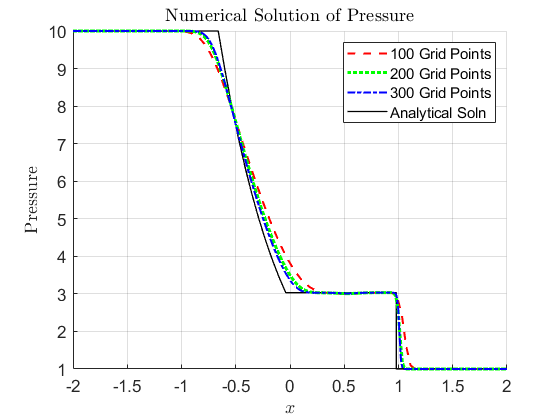

figure (2)
hold on
p_anal = plot(x_shock, p_shock, 'k', 'LineWidth', 1);
p_100 = plot(x_100, p(1,1:100), '--', 'MarkerSize', 4, 'color', 'r', 'LineWidth', 1.5); % o
p_200 = plot(x_200, p(2,1:200), ':', 'MarkerSize', 4, 'color', 'g', 'LineWidth', 2.25); % x
p_300 = plot(x_300, p(3,1:300), '-.', 'MarkerSize', 4, 'color', 'b', 'LineWidth', 1.5); % ^
title('Numerical Solution of Pressure', 'interpreter', 'latex', 'FontSize', 10);
ylabel('Pressure', 'interpreter', 'latex', 'FontSize', 10), xlabel('$x$', 'interpreter', 'latex', 'FontSize', 10);
set(gca, 'FontSize', 12.5);
L = legend([p_100 p_200 p_300 p_anal], '100 Grid Points', '200 Grid Points', '300 Grid Points', 'Analytical Soln', 'Location', 'Northeast');
L.FontSize = 11;
% xlim([0.5 1.5]), ylim([2 4]);
grid on
hold off

## Velocity

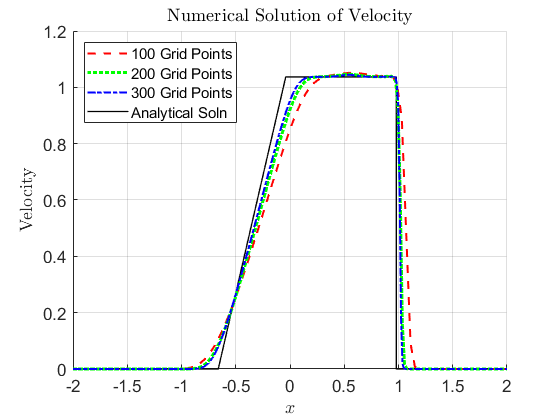

figure (3)
hold on
vel_anal = plot(x_shock, v_shock, 'k', 'LineWidth', 1);
vel_100 = plot(x_100, u(1,1:100), '--', 'MarkerSize', 4, 'color', 'r', 'LineWidth', 1.5); % o
vel_200 = plot(x_200, u(2,1:200), ':', 'MarkerSize', 4, 'color', 'g', 'LineWidth', 2.25); % x
vel_300 = plot(x_300, u(3,1:300), '-.', 'MarkerSize', 4, 'color', 'b', 'LineWidth', 1.5); % ^
title('Numerical Solution of Velocity', 'interpreter', 'latex', 'FontSize', 10);
ylabel('Velocity', 'interpreter', 'latex', 'FontSize', 10), xlabel('$x$', 'interpreter', 'latex', 'FontSize', 10);
set(gca, 'FontSize', 12.5);
L = legend([vel_100 vel_200 vel_300 vel_anal], '100 Grid Points', '200 Grid Points', '300 Grid Points', 'Analytical Soln', 'Location', 'Northwest');
L.FontSize = 11;
% xlim([0 1.5]), ylim([0.6 1.4]);
grid on
hold off

## Mach Number

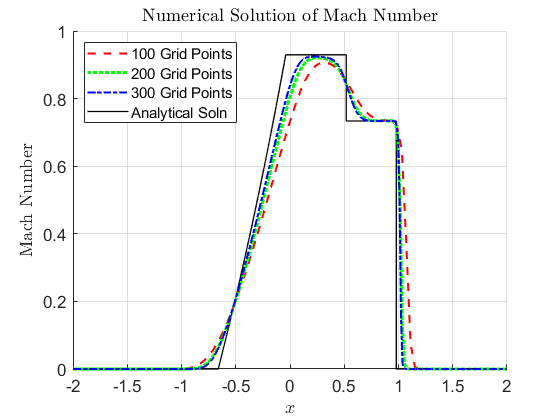

figure (4)
hold on
mach_anal = plot(x_shock, m_shock, 'k', 'LineWidth', 1);
mach_100 = plot(x_100, Mach(1,1:100), '--', 'MarkerSize', 4, 'color', 'r', 'LineWidth', 1.5); % o
mach_200 = plot(x_200, Mach(2,1:200), ':', 'MarkerSize', 4, 'color', 'g', 'LineWidth', 2.25); % x
mach_300 = plot(x_300, Mach(3,1:300), '-.', 'MarkerSize', 4, 'color', 'b', 'LineWidth', 1.5); % ^
title('Numerical Solution of Mach Number', 'interpreter', 'latex', 'FontSize', 10);
ylabel('Mach Number', 'interpreter', 'latex', 'FontSize', 10), xlabel('$x$', 'interpreter', 'latex', 'FontSize', 10);
set(gca, 'FontSize', 12.5);
L = legend([mach_100 mach_200 mach_300 mach_anal], '100 Grid Points', '200 Grid Points', '300 Grid Points', 'Analytical Soln', 'Location', 'Northwest');
L.FontSize = 11;
% xlim([0 1.5]), ylim([0.4 1.0]);
grid on
hold off

## Entropy/Cv

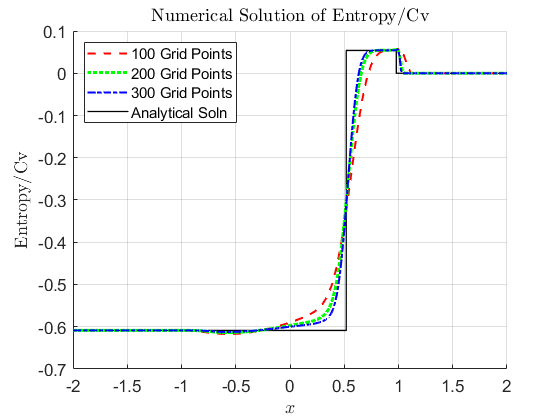

figure (5)
hold on
ent_anal = plot(x_shock, e_shock, 'k', 'LineWidth', 1);
ent_100 = plot(x_100, ent(1,1:100), '--', 'MarkerSize', 4, 'color', 'r', 'LineWidth', 1.5); % o
ent_200 = plot(x_200, ent(2,1:200), ':', 'MarkerSize', 4, 'color', 'g', 'LineWidth', 2.25); % x
ent_300 = plot(x_300, ent(3,1:300), '-.', 'MarkerSize', 4, 'color', 'b', 'LineWidth', 1.5); % ^
title('Numerical Solution of Entropy/Cv', 'interpreter', 'latex', 'FontSize', 10);
ylabel('Entropy/Cv', 'interpreter', 'latex', 'FontSize', 10), xlabel('$x$', 'interpreter', 'latex', 'FontSize', 10);
set(gca,'FontSize', 12.5);
L = legend([ent_100 ent_200 ent_300 ent_anal], '100 Grid Points', '200 Grid Points', '300 Grid Points', 'Analytical Soln', 'Location', 'Northwest');
L.FontSize = 11;
% xlim([0 1.5]), ylim([-0.1 0.1]);
grid on
hold off